### Task1

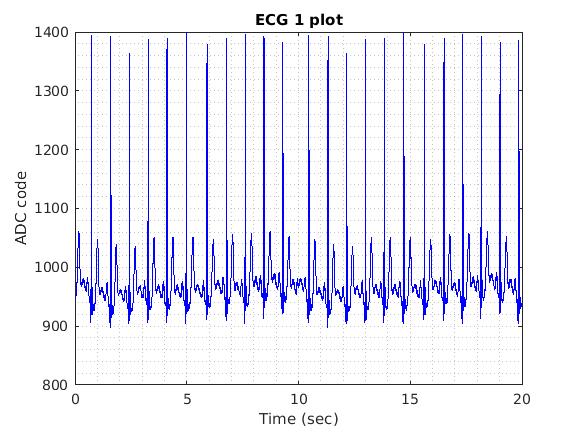

clc
clear all

% plotting ECG1
load ECG_case_1.mat


t = 0:(1/Fs):(length(ECG)-1)*(1/Fs); %time vector for ECG1

plot (t,ECG,"b")
xlabel ("Time (sec)")
ylabel ("ADC code")

title 'ECG 1 plot'
grid minor 

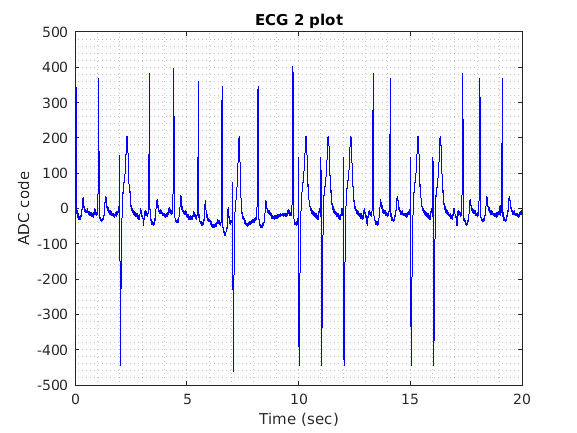


%plotting ECG2
load ECG_case_2.mat

t = 0:(1/Fs):(length(ECG)-1)*(1/Fs); %time vector for ECG2

plot (t,ECG,"b")
xlabel ("Time (sec)")
ylabel ("ADC code")

title 'ECG 2 plot'
grid minor 

### Task 2

load ECG_case_1.mat
[x,f] = frft (ECG, Fs);

%filtering out the part that is not withing in 0.5-45Hz range
fcutoff_top = 45;
fcutoff_bottom = 0.5;

diff = f(2) - f(1);

fcutoff_bottomidx = ceil(fcutoff_bottom/diff);
fcutoff_topidx = ceil(fcutoff_top/diff) ;

%equating the parts that aren't in the range to zero
ECGfiltered = x;
ECGfiltered (1 : fcutoff_bottomidx) = 0;
ECGfiltered (fcutoff_topidx : end) = 0;

%ECGfiltered is the final filtered signal
t = 0:(1/Fs):(length(ECG)-1)*(1/Fs);

%finding inverse fourier transform so that we can plot filtered signal
[ECG_filtered,t] = invfrft (ECGfiltered,f,Fs);


%using the number of R peaks to find heart rate
plot (t, ECG_filtered,'b')
MinDist = 280;
[peaks, locations] = findpeaks(ECG_filtered,"MinPeakDistance",MinDist)

peaks =   421.3226  428.6782  401.3376  418.5146  425.2621  427.4339  403.6569  414.7380  417.9965  410.8701  402.8077  426.1016  426.6661  402.4180  418.1369  425.3554  427.7462  403.2941  415.2525  417.3407  411.5474  402.3624  413.8328


locations =          266         577         877        1181        1483        1796        2129        2445        2746        3045        3348        3767        4078        4378        4682        4984        5297        5630        5946        6247        6546        6849        7149


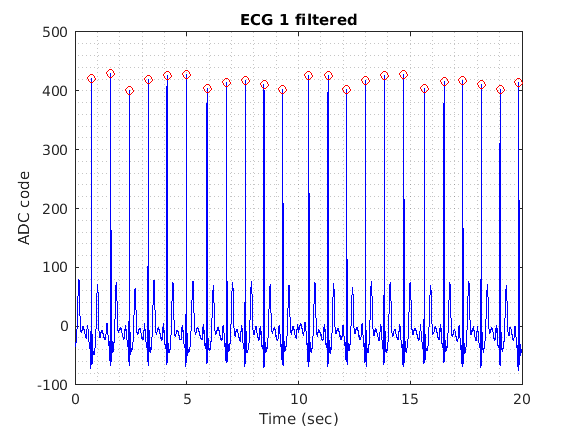

hold on
grid minor

plot (locations/Fs , peaks ,"red o")
xlabel ("Time (sec)")
ylabel ('ADC code')
title 'ECG 1 filtered'


HeartRate = ((length (peaks))/t(end) * 60)

HeartRate = 69

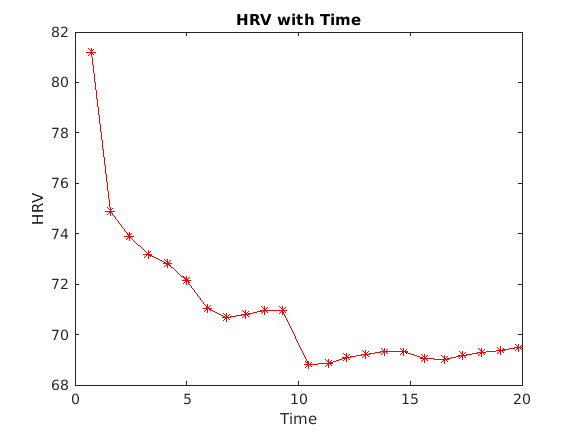


%finding HRV in sample
HRV=[];
for s =1:length(locations)
    i = s/(locations(s)/Fs)*60;
    HRV=[HRV, i];
end

%plotting HRV with time
figure
plot (locations/Fs , HRV,'*-r')
xlabel ('Time')
ylabel ('HRV')

title 'HRV with Time'

### Task 3

%plot of filtered ECG1 graph for labels of minima and maxima
plot (t, ECG_filtered,'magenta')
ylabel ('ADC code')
xlabel ('Time (sec)')

title 'ECG 1 (labelled) '

hold on
grid minor


%finding and plotting R wave on graph
[Rwave, locations] =findpeaks(ECG_filtered,'MinPeakProminence',160)

Rwave =   421.3226  428.6782  401.3376  418.5146  425.2621  427.4339  403.6569  414.7380  417.9965  410.8701  402.8077  426.1016  426.6661  402.4180  418.1369  425.3554  427.7462  403.2941  415.2525  417.3407  411.5474  402.3624  413.8328


locations =          266         577         877        1181        1483        1796        2129        2445        2746        3045        3348        3767        4078        4378        4682        4984        5297        5630        5946        6247        6546        6849        7149


plot (locations/Fs , Rwave, "or")

%finding and plotting Twave on graph
[Twave, locations] = findpeaks(ECG_filtered,Fs,'MinPeakWidth',.08,'MinPeakHeight',50)

Twave =    80.0226   71.2357   74.7750   64.3020   77.2766   74.3238   75.4791   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825   65.6006   76.2442   74.9638   74.9803   69.9008   74.2632   76.2288   71.2241   68.9131


locations =     0.1750    1.0083    1.8500    2.6889    3.5361    4.3778    5.2806    6.1889    7.0472    7.8972    8.7306    9.5778   10.7333   11.5750   12.4139   13.2611   14.1028   15.0056   15.9139   16.7722   17.6222   18.4556   19.3000


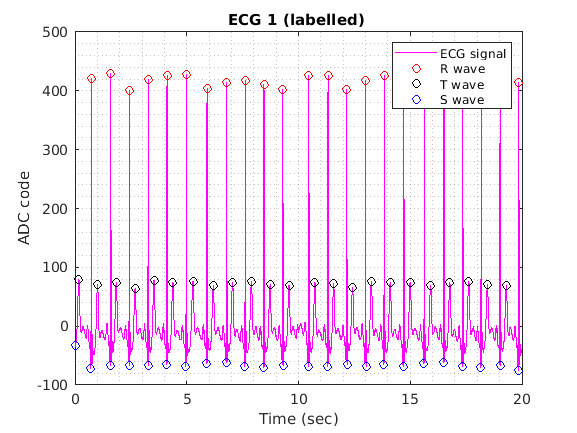

plot (locations , Twave, "oblack")



ECG_filteredcropped = ECG_filtered;
tallPeakIndexes = ECG_filtered < -60 ; % Thresold
ECG_filteredcropped(tallPeakIndexes) = 0;  %set zero to all values less than -60


%finding and plotting Swave on graph
ECGinv = -ECG_filtered;
[Swave, locations] = findpeaks(ECGinv, 'MinPeakHeight',0.5,'MinPeakDistance',220);
plot (t(locations),ECG_filtered(locations),'oblue')

%adding legend
legend('ECG signal', 'R wave ','T wave ', 'S wave') 
hold off

### Task 4

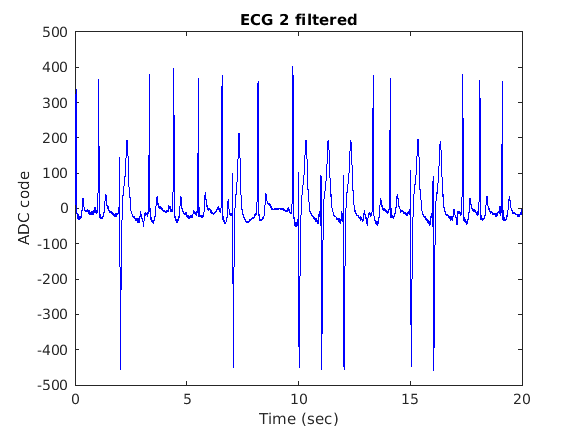

load ECG_case_2.mat


[X,F] = frft (ECG, Fs);

%%filtering out the part that is not withing in 0.5-45Hz range

fcutoff_top = 45;
fcutoff_bottom = 0.5;

diff = F(2) - F(1);

fcutoff_bottomidx = ceil(fcutoff_bottom/diff);
fcutoff_topidx = ceil(fcutoff_top/diff);

%equating the parts that aren't in the range to zero
ECG2filtered = X;
ECG2filtered (1 : fcutoff_bottomidx) = 0;
ECG2filtered (fcutoff_topidx : end) = 0;

%ECG2filtered is the final filtered signal


%finding inverse fourier transform so that we can plot filtered signal
[ECG2_filtered,t] = invfrft (ECG2filtered,F,Fs);


plot (t, ECG2_filtered,'b')
title 'ECG 2 filtered'
xlabel 'Time (sec)'
ylabel 'ADC code'


%plot of filtered ECG2 graph for labels of minima and maxima
plot (t, ECG2_filtered,'magenta')
ylabel ('ADC code')
xlabel ('Time (sec)')

title 'ECG 2 (filtered and labelled)'

hold on
grid minor

%finding and plotting R wave on graph
[Rwave, locations] =findpeaks(ECG2_filtered,'MinPeakProminence',350,'MinPeakHeight',230)

Rwave =   366.4297  378.7639  396.7518  368.4616  376.2780  359.8155  403.0283  375.8440  367.9245  378.3755  362.4885  360.5396


locations =          384        1200        1592        1990        2370        2949        3511        4804        5079        6248        6523        6884


plot (locations/Fs , Rwave, "or")

%finding and plotting Twave on graph
ECG2_filteredcropped=ECG2_filtered

ECG2_filteredcropped =    10.2734   19.7600   27.1382   32.6952   38.3381   46.5637   59.0633   75.7676   94.9345  114.3069  132.7231  151.2122  172.7762  200.7181  236.1894  276.1903  313.2107  337.0339  338.2048  311.8001  259.8557  191.2969  119.2622   56.8538   13.0247   -9.7656  -15.3124  -11.1694   -5.1555   -2.4322   -4.2909   -8.8805  -13.1900  -15.1076  -14.5226  -13.0652  -12.8475  -15.0528  -19.2076  -23.5029  -25.9097  -25.3963  -22.5351  -19.1714  -17.3679  -18.2445  -21.3678  -25.0190  -27.1691  -26.6034



tallPeakIndexes = ECG2_filtered > 200; % Thresold
ECG2_filteredcropped(tallPeakIndexes) = 0;  %set zero to all values greater than 200

[Twave, locations] =findpeaks(ECG2_filteredcropped,Fs,'MinPeakWidth',.06,'MinPeakHeight',10)

Twave =    27.9909   39.1877  191.9936   32.6364  194.9180   32.7206   45.2340  199.2167   42.7759  192.9166  192.1175  192.2348   28.1035   40.8178  194.7634  190.0759   27.1403   34.9307   33.2921


locations =     0.3639    1.3778    2.3250    3.6722    4.4028    4.7250    5.8389    7.3222    8.5333   10.3361   11.3389   12.3306   13.6833   14.4194   15.3389   16.3417   17.6944   18.4306   19.4361


plot (locations , Twave, "oblack")


%finding and plotting Swave on graph
ECG2_filteredcropped = ECG2_filtered

ECG2_filteredcropped =    10.2734   19.7600   27.1382   32.6952   38.3381   46.5637   59.0633   75.7676   94.9345  114.3069  132.7231  151.2122  172.7762  200.7181  236.1894  276.1903  313.2107  337.0339  338.2048  311.8001  259.8557  191.2969  119.2622   56.8538   13.0247   -9.7656  -15.3124  -11.1694   -5.1555   -2.4322   -4.2909   -8.8805  -13.1900  -15.1076  -14.5226  -13.0652  -12.8475  -15.0528  -19.2076  -23.5029  -25.9097  -25.3963  -22.5351  -19.1714  -17.3679  -18.2445  -21.3678  -25.0190  -27.1691  -26.6034


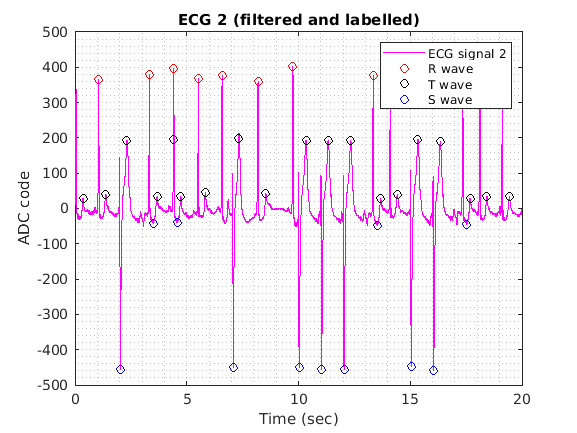


tallPeakIndexes = ECG2_filtered < -30 ; % Threshold
ECG2_filteredcropped(tallPeakIndexes) = 0;  %set zero to all values less than -30

ECG2inv = -ECG2_filtered;
[Swave, locations] = findpeaks(ECG2inv,'MinPeakProminence',400,'MinPeakDistance',220);
plot (t(locations),ECG2_filtered(locations),'oblue')


%adding legend
legend('ECG signal 2', 'R wave ','T wave ', 'S wave') 
hold off

### Task 5



load ECG_case_2.mat



[Rwave, locations] =findpeaks(ECG2_filtered,'MinPeakProminence',350,'MinPeakHeight',230)

Rwave =   366.4297  378.7639  396.7518  368.4616  376.2780  359.8155  403.0283  375.8440  367.9245  378.3755  362.4885  360.5396


locations =          384        1200        1592        1990        2370        2949        3511        4804        5079        6248        6523        6884




%%%making vector containing index where there is R waves and the time where R
%wave occurs
j = 1

j = 1

k=1

k = 1

points_R=locations/Fs

points_R =     1.0667    3.3333    4.4222    5.5278    6.5833    8.1917    9.7528   13.3444   14.1083   17.3556   18.1194   19.1222


for i=1:length(locations)
    R=Rwave(i)
   time_Rwaves = points_R(i)
   if R>300||R<150 && R>50
       index_R_time(j)=time_Rwaves
       j = j + 1
    end
end

R = 366.4297

time_Rwaves = 1.0667

index_R_time = 1.0667

j = 2

R = 378.7639

time_Rwaves = 3.3333

index_R_time =     1.0667    3.3333


j = 3

R = 396.7518

time_Rwaves = 4.4222

index_R_time =     1.0667    3.3333    4.4222


j = 4

R = 368.4616

time_Rwaves = 5.5278

index_R_time =     1.0667    3.3333    4.4222    5.5278


j = 5

R = 376.2780

time_Rwaves = 6.5833

index_R_time =     1.0667    3.3333    4.4222    5.5278    6.5833


j = 6

R = 359.8155

time_Rwaves = 8.1917

index_R_time =     1.0667    3.3333    4.4222    5.5278    6.5833    8.1917


j = 7

R = 403.0283

time_Rwaves = 9.7528

index_R_time =     1.0667    3.3333    4.4222    5.5278    6.5833    8.1917    9.7528


j = 8

R = 375.8440

time_Rwaves = 13.3444

index_R_time =     1.0667    3.3333    4.4222    5.5278    6.5833    8.1917    9.7528   13.3444


j = 9

R = 367.9245

time_Rwaves = 14.1083

index_R_time =     1.0667    3.3333    4.4222    5.5278    6.5833    8.1917    9.7528   13.3444   14.1083


j = 10

R = 378.3755

time_Rwaves = 17.3556

index_R_time =     1.0667    3.3333    4.4222    5.5278    6.5833    8.1917    9.7528   13.3444   14.1083   17.3556


j = 11

R = 362.4885

time_Rwaves = 18.1194

index_R_time =     1.0667    3.3333    4.4222    5.5278    6.5833    8.1917    9.7528   13.3444   14.1083   17.3556   18.1194


j = 12

R = 360.5396

time_Rwaves = 19.1222

index_R_time =     1.0667    3.3333    4.4222    5.5278    6.5833    8.1917    9.7528   13.3444   14.1083   17.3556   18.1194   19.1222


j = 13




%finding RR interval

Rcount=1

Rcount = 1

for i=1: length(Rwave)-1
    RRinterval(Rcount)= index_R_time (i+1) - index_R_time (i)
    Rcount = Rcount + 1
end

RRinterval =     2.2667    1.0889    1.1056    1.0556    1.6083    1.5611    3.5917    0.7639    3.2472    0.7639    1.0028


Rcount = 2

RRinterval =     2.2667    1.0889    1.1056    1.0556    1.6083    1.5611    3.5917    0.7639    3.2472    0.7639    1.0028


Rcount = 3

RRinterval =     2.2667    1.0889    1.1056    1.0556    1.6083    1.5611    3.5917    0.7639    3.2472    0.7639    1.0028


Rcount = 4

RRinterval =     2.2667    1.0889    1.1056    1.0556    1.6083    1.5611    3.5917    0.7639    3.2472    0.7639    1.0028


Rcount = 5

RRinterval =     2.2667    1.0889    1.1056    1.0556    1.6083    1.5611    3.5917    0.7639    3.2472    0.7639    1.0028


Rcount = 6

RRinterval =     2.2667    1.0889    1.1056    1.0556    1.6083    1.5611    3.5917    0.7639    3.2472    0.7639    1.0028


Rcount = 7

RRinterval =     2.2667    1.0889    1.1056    1.0556    1.6083    1.5611    3.5917    0.7639    3.2472    0.7639    1.0028


Rcount = 8

RRinterval =     2.2667    1.0889    1.1056    1.0556    1.6083    1.5611    3.5917    0.7639    3.2472    0.7639    1.0028


Rcount = 9

RRinterval =     2.2667    1.0889    1.1056    1.0556    1.6083    1.5611    3.5917    0.7639    3.2472    0.7639    1.0028


Rcount = 10

RRinterval =     2.2667    1.0889    1.1056    1.0556    1.6083    1.5611    3.5917    0.7639    3.2472    0.7639    1.0028


Rcount = 11

RRinterval =     2.2667    1.0889    1.1056    1.0556    1.6083    1.5611    3.5917    0.7639    3.2472    0.7639    1.0028


Rcount = 12



%%loop that checks condition for PVC and displays message if arrythmia
%detected
k=1

k = 1

t=1

t = 1

for i=1:length (locations)
    if RRinterval<0.6
       msgbox ('Arrythmia Detected', t)
       k = k+1
    end
    i=i+1
    t = t+0.5
end

i = 2

t = 1.5000

i = 3

t = 2

i = 4

t = 2.5000

i = 5

t = 3

i = 6

t = 3.5000

i = 7

t = 4

i = 8

t = 4.5000

i = 9

t = 5

i = 10

t = 5.5000

i = 11

t = 6

i = 12

t = 6.5000

i = 13

t = 7